# **LiveScript Data Processing - Merbouche Mouloud & Tso Célia**

clear
close all 
clc
load('Data-20251007/q.mat')
load('Data-20251007/tau.mat')
q_rad = deg2rad(q_meas);
fc = 10;
fe = 1000;
Wn = 2*fc/fe;
[b,a] = butter(1,Wn);
qf = filtfilt(b,a,q_rad);%filtrage
tauf = filtfilt(b,a,Tau);%filtrage

function df = derive(t,f)
df = [ f(1,2) - f(1,1) , (f(1,3:end) - f(1,1:end-2))/2 , f(1,end)-f(1,end-1)]/(t(1,2)-t(1,1));
end


velo = [];
for i = 1:size(qf, 1) %vitesse pr chaque articulation donc chaque ligne de qf
    velo(i, :) = derive(t, qf(i, :));
end
dqf = filtfilt(b, a, velo); %filtrage


accel=[];
for i = 1:size(dqf, 1) % accélération pr chaque articulation donc chaque ligne de qf
    accel(i, :) = derive(t, dqf(i, :));
end
ddqf = filtfilt(b,a,accel);%filtrage

save("q_rad.mat","q_rad");
save("qf.mat","qf");
save("dqf.mat","dqf");
save("ddqf.mat","ddqf");
save("tauf.mat","tauf");

**Joint Position**

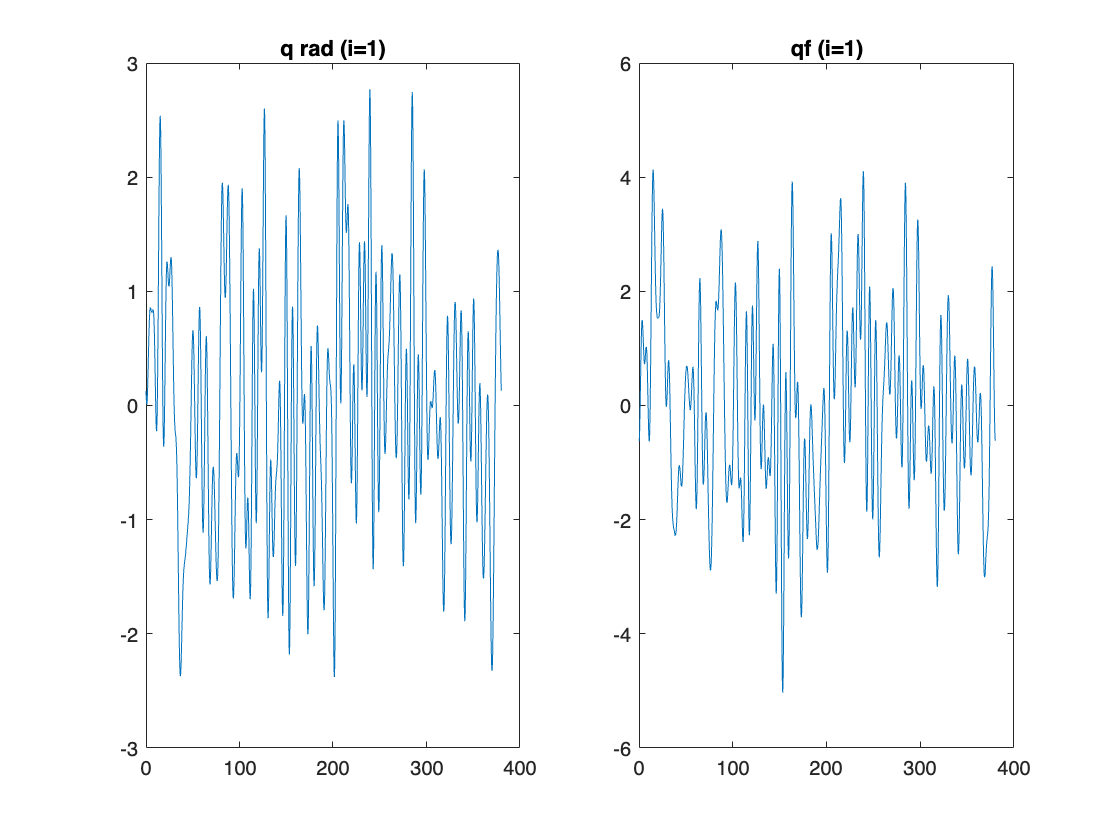

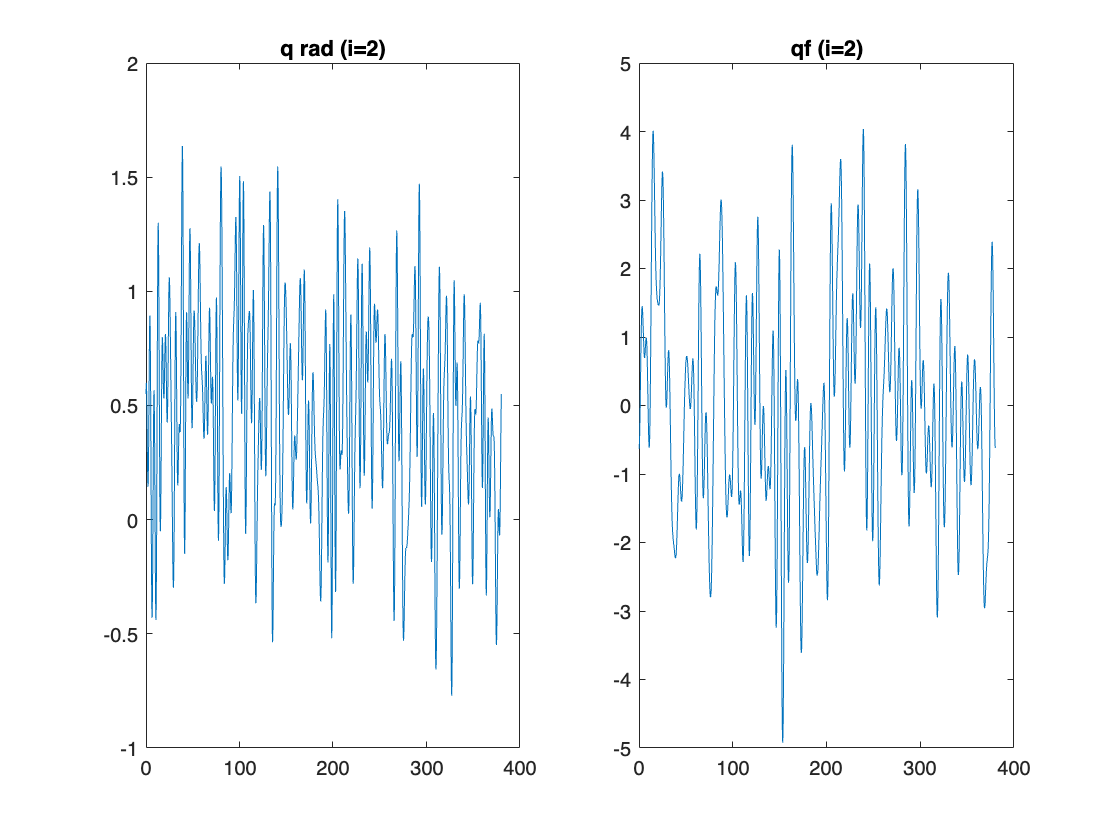

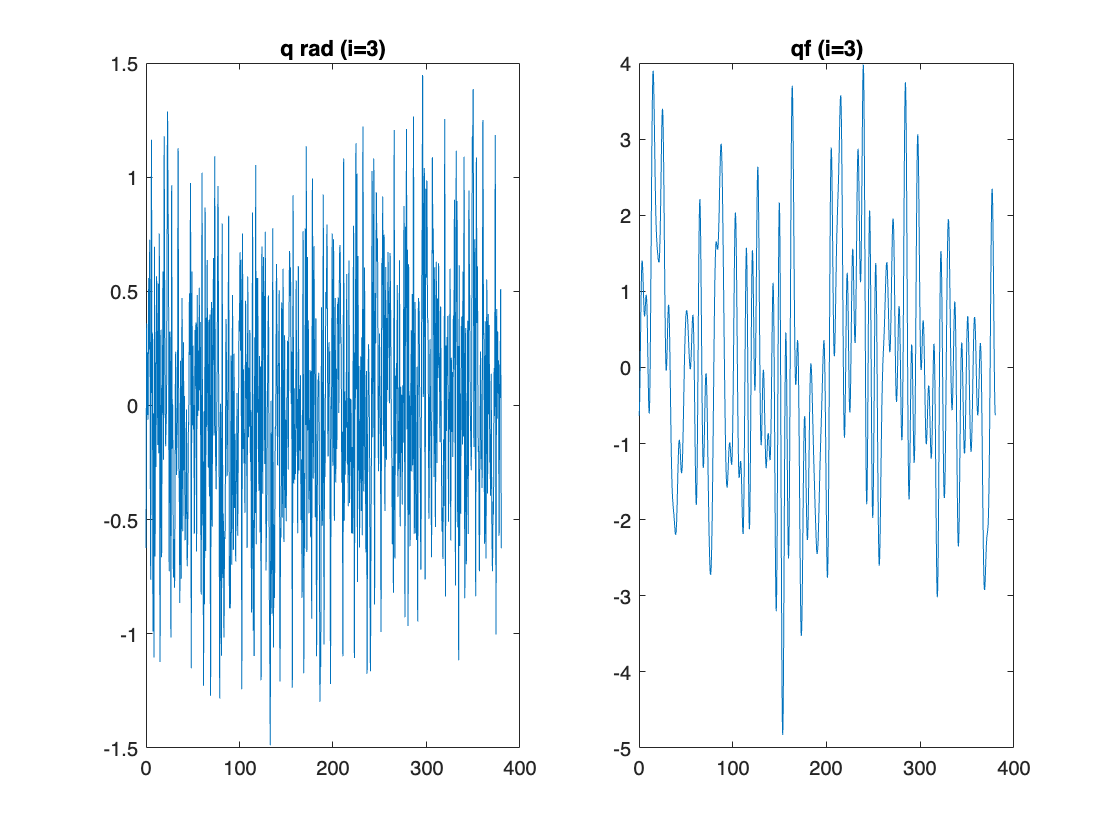

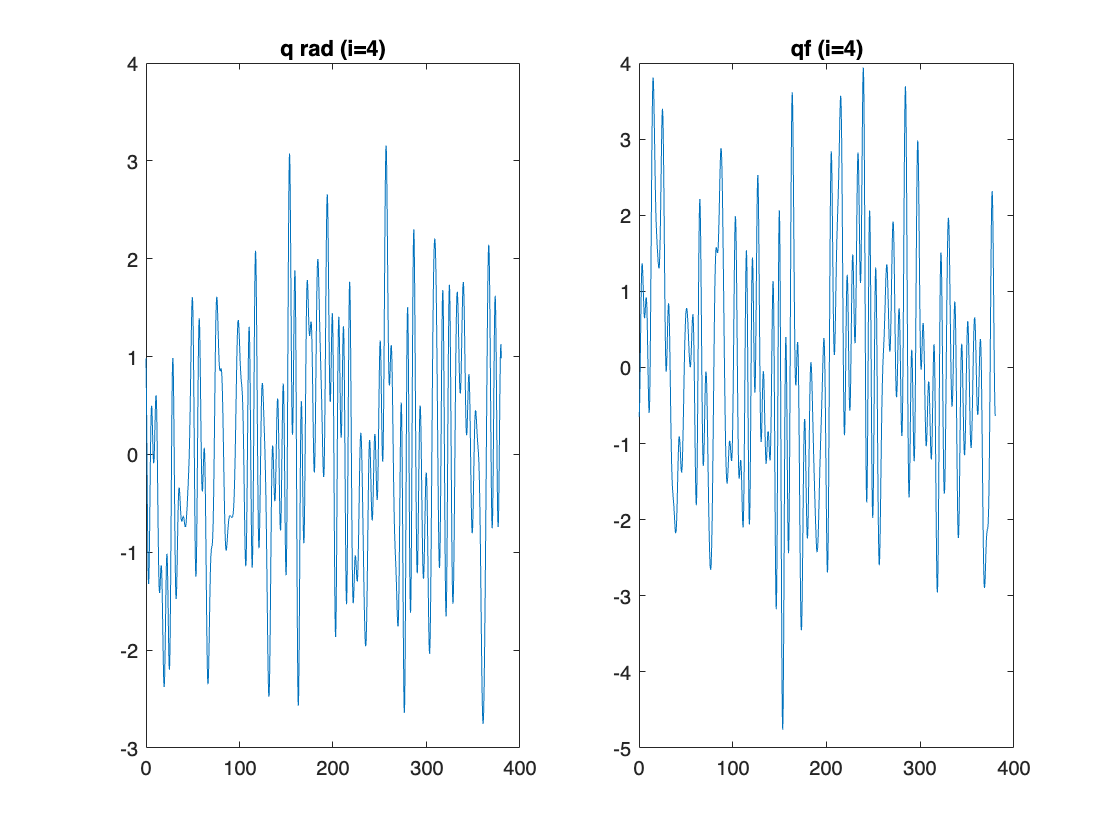

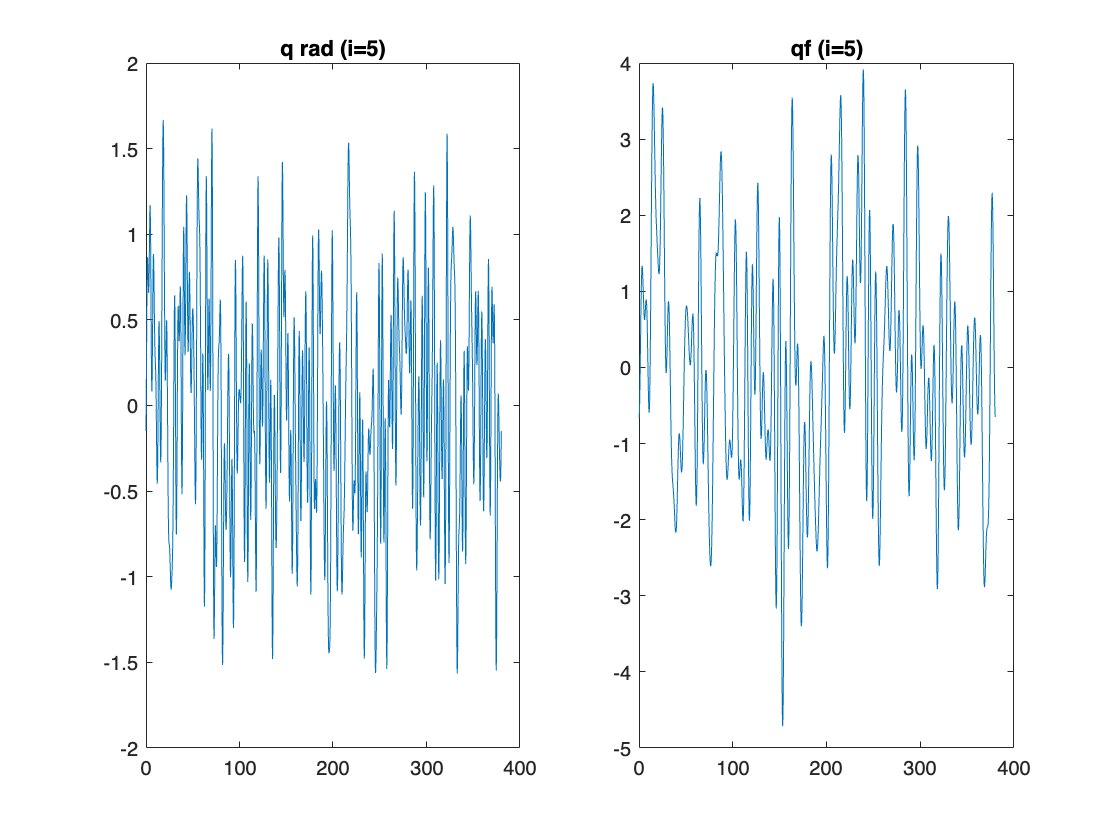

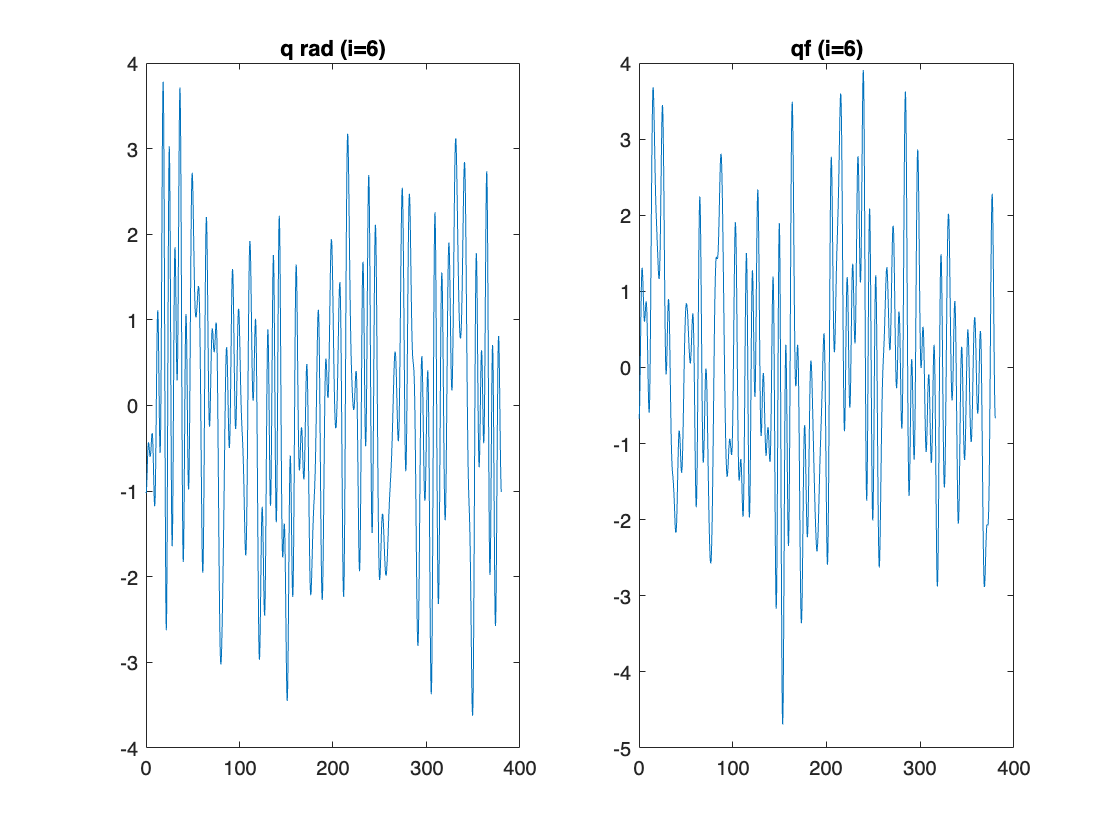

for i = 1:6
    f = figure('Name', sprintf('Joint Position : q_%d', i)); 
    subplot(1,2,1); 
    plot(t, q_rad(i,:)); 
    title(sprintf('q rad (i=%d)', i));
    subplot(1,2,2); 
    plot(t, qf(i,:));    
    title(sprintf('qf (i=%d)', i));
end

**Joint Velocity **

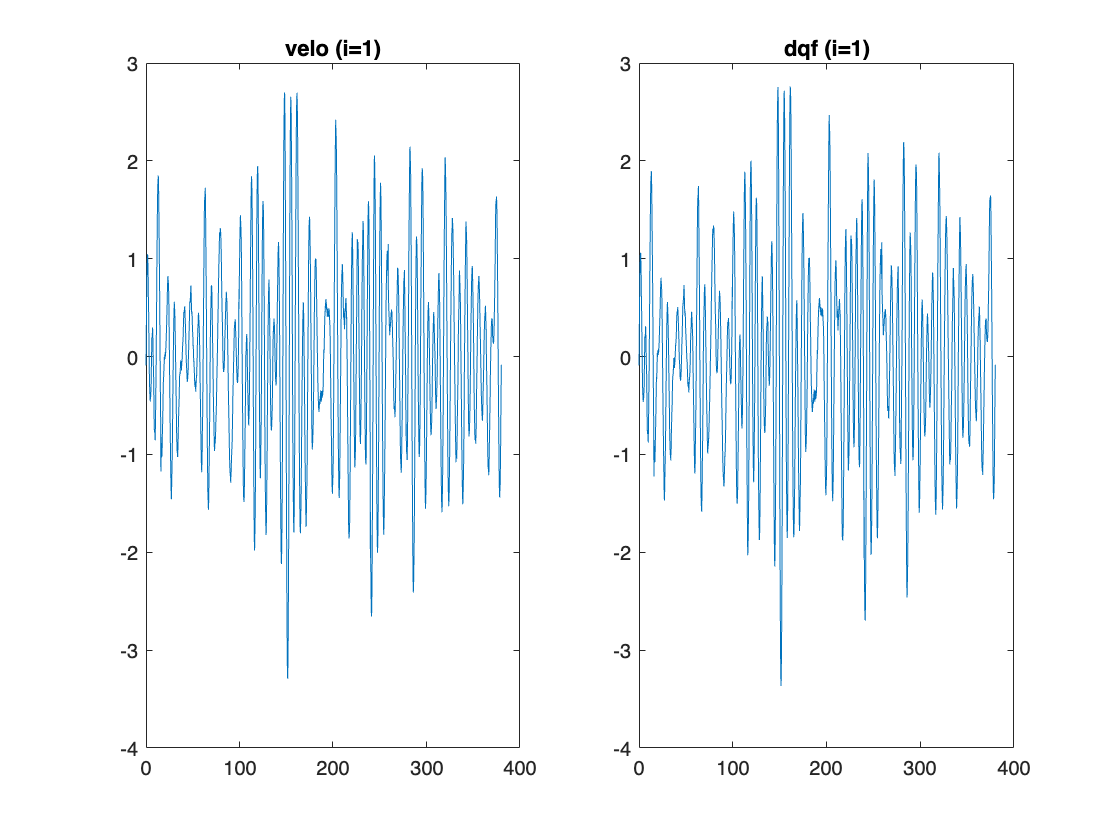

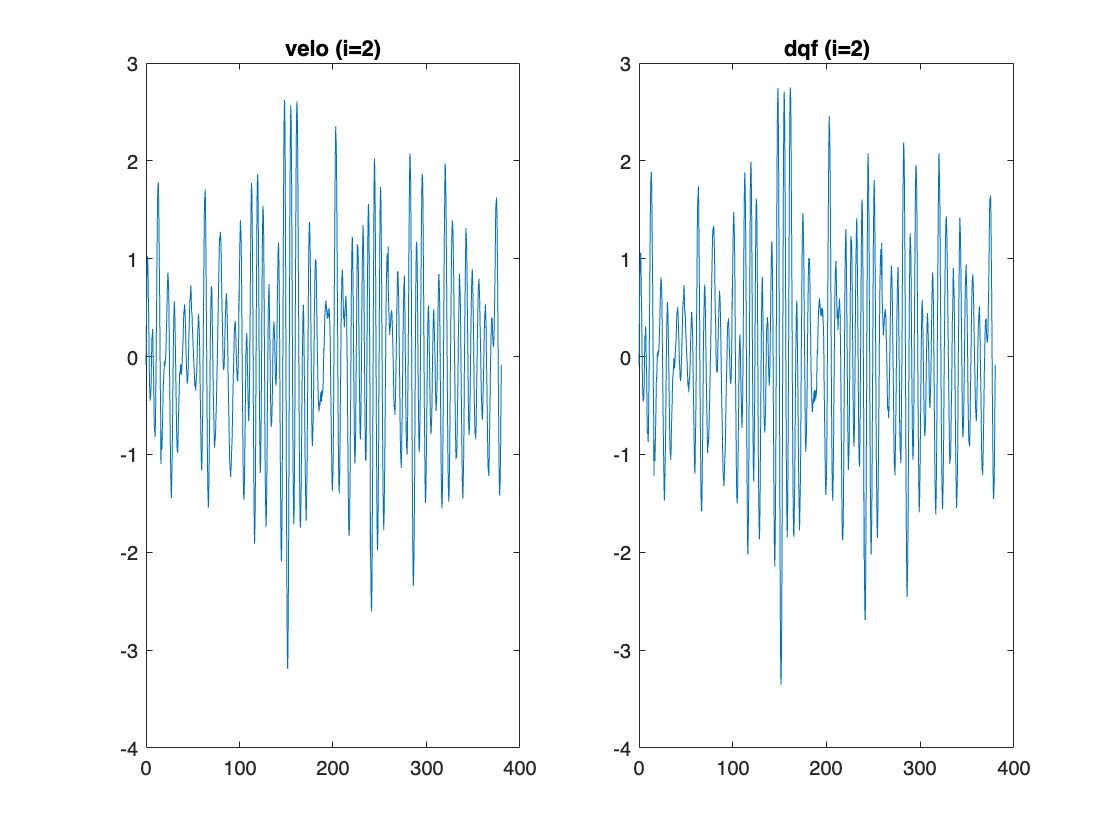

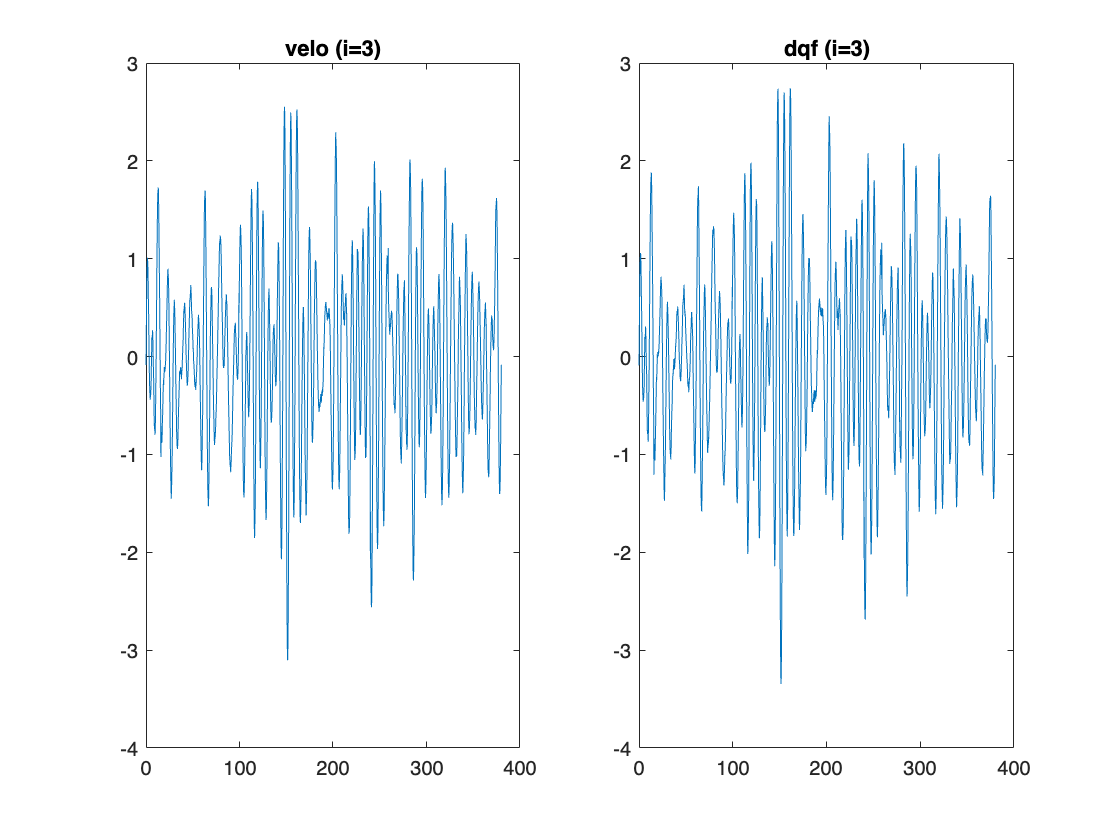

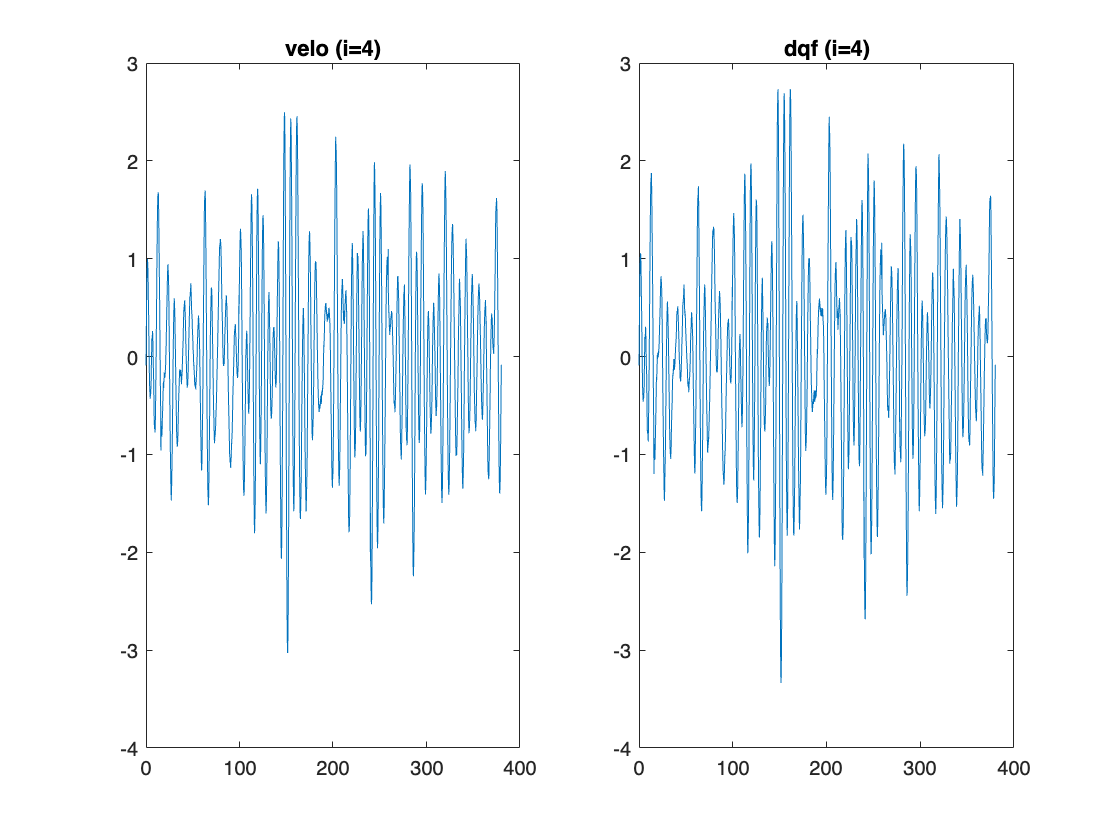

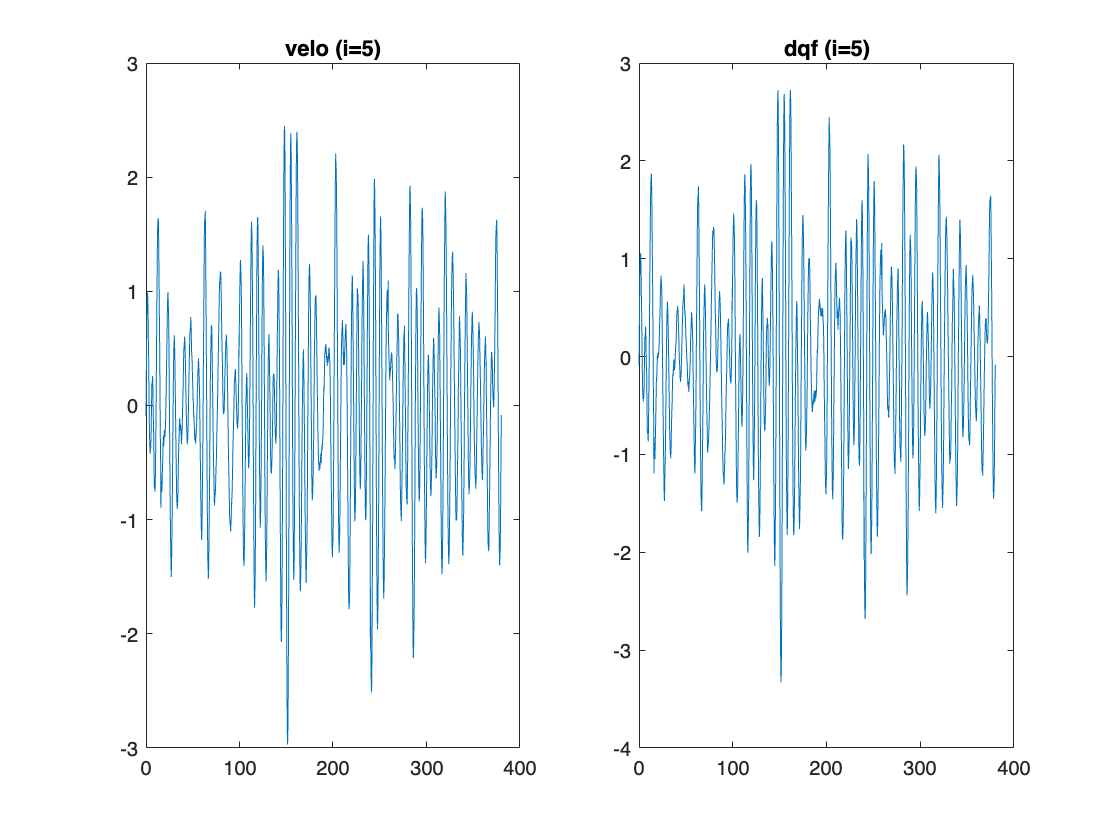

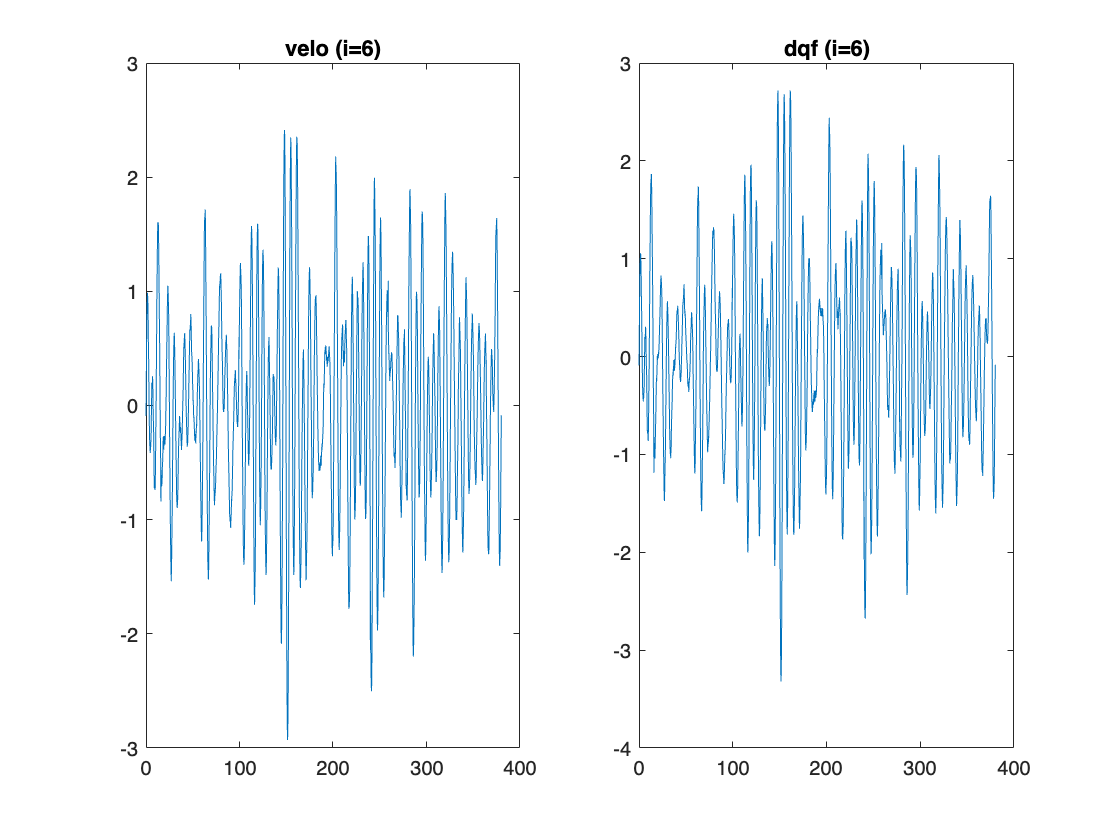

for i = 1:6
    f = figure('Name', sprintf('Joint Velocity : q_%d', i)); 
    subplot(1,2,1); 
    plot(t, velo(i,:)); 
    title(sprintf('velo (i=%d)', i));
    subplot(1,2,2); 
    plot(t, dqf(i,:));    
    title(sprintf('dqf (i=%d)', i));
end

**Joint Acceleration**

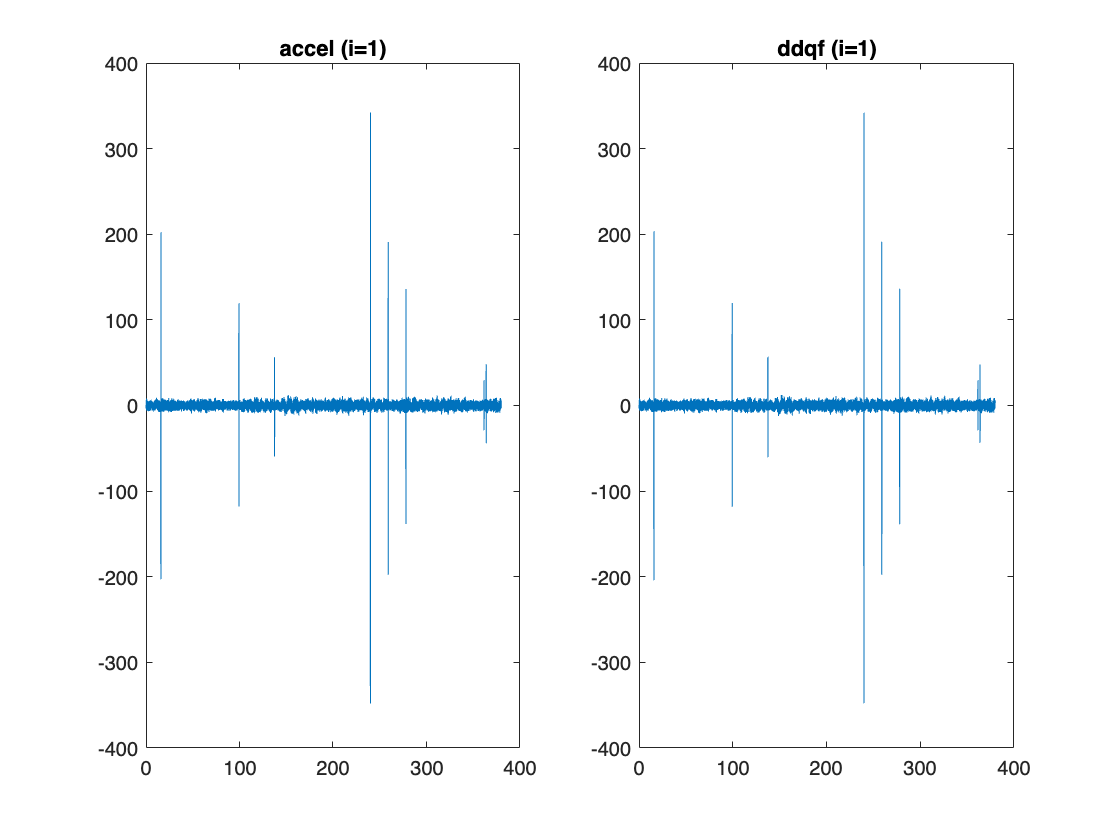

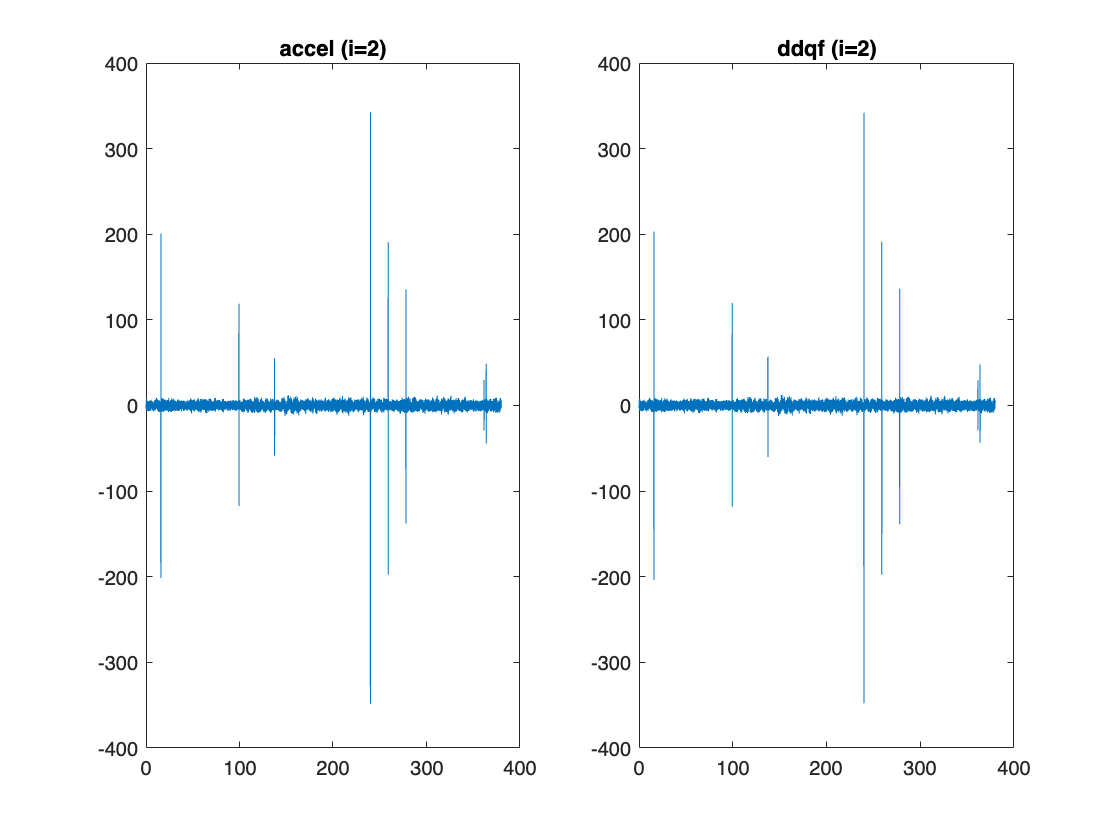

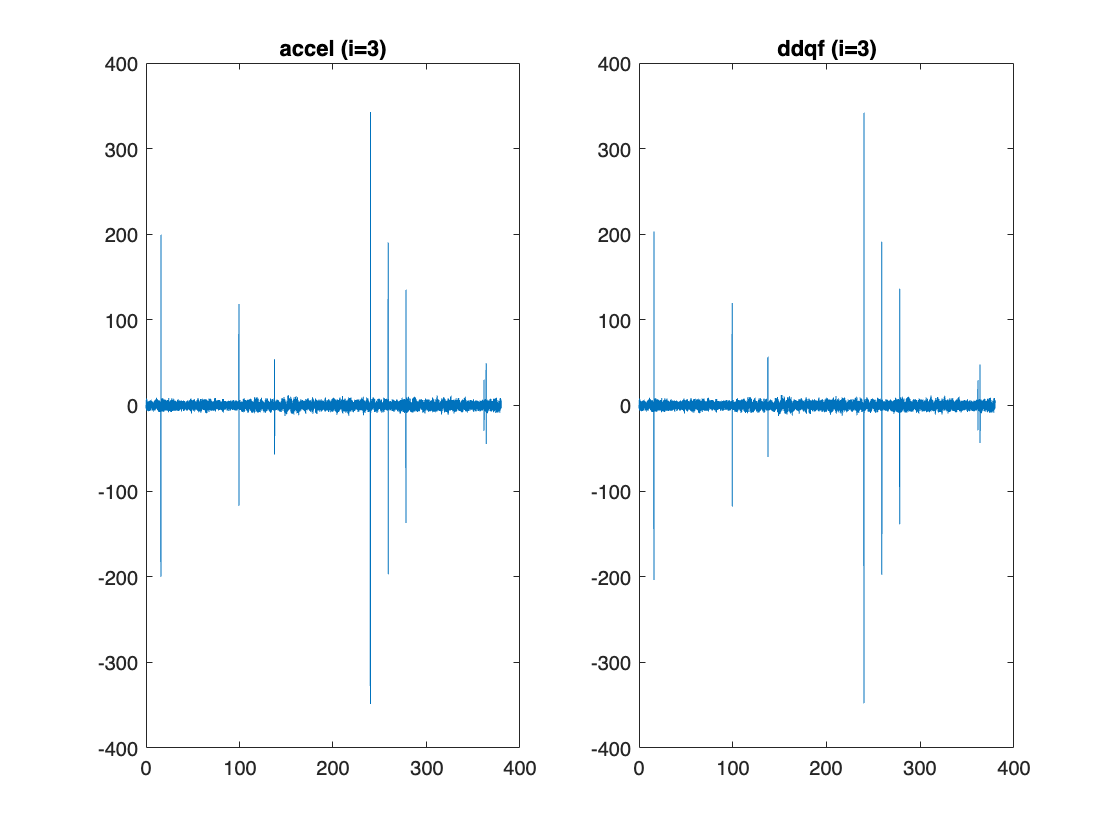

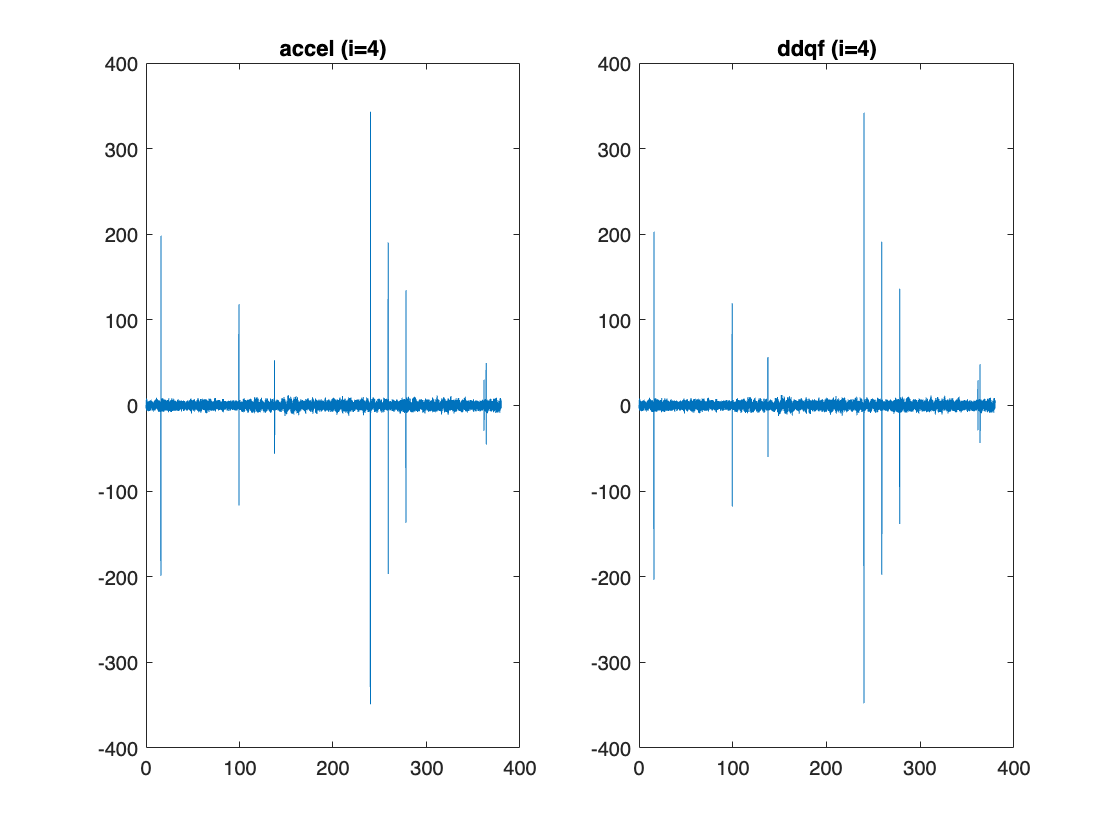

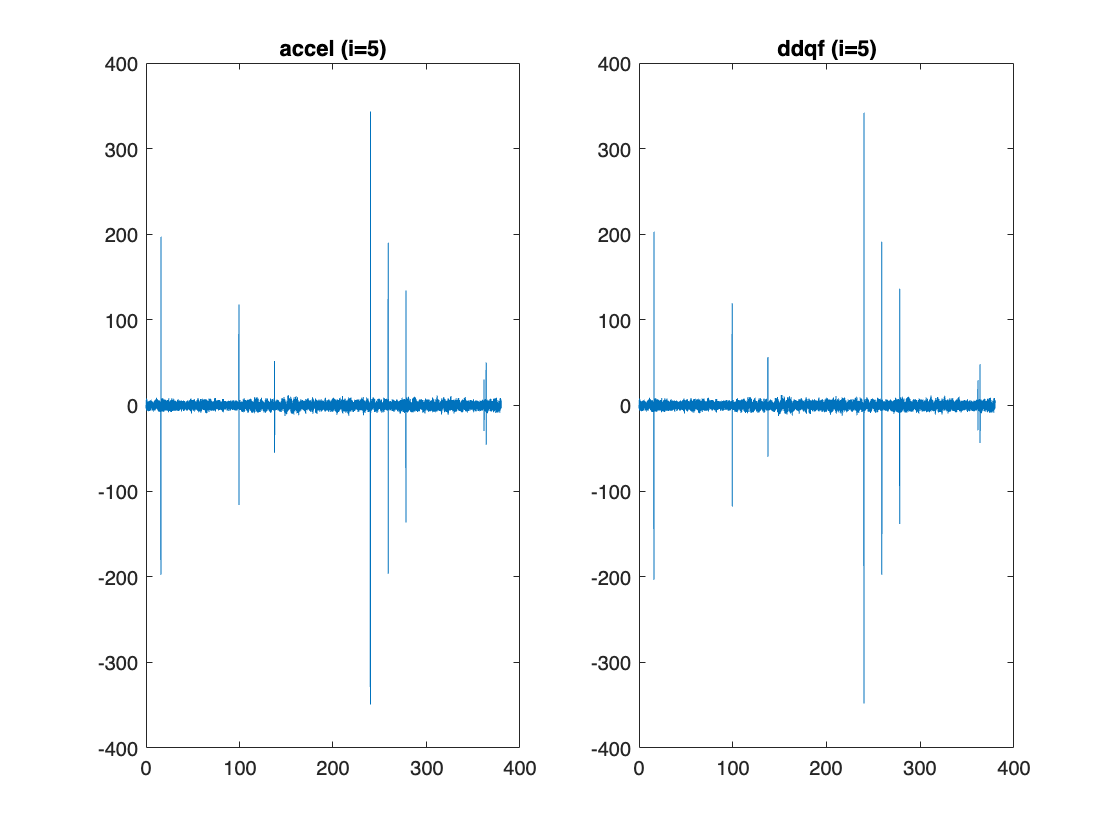

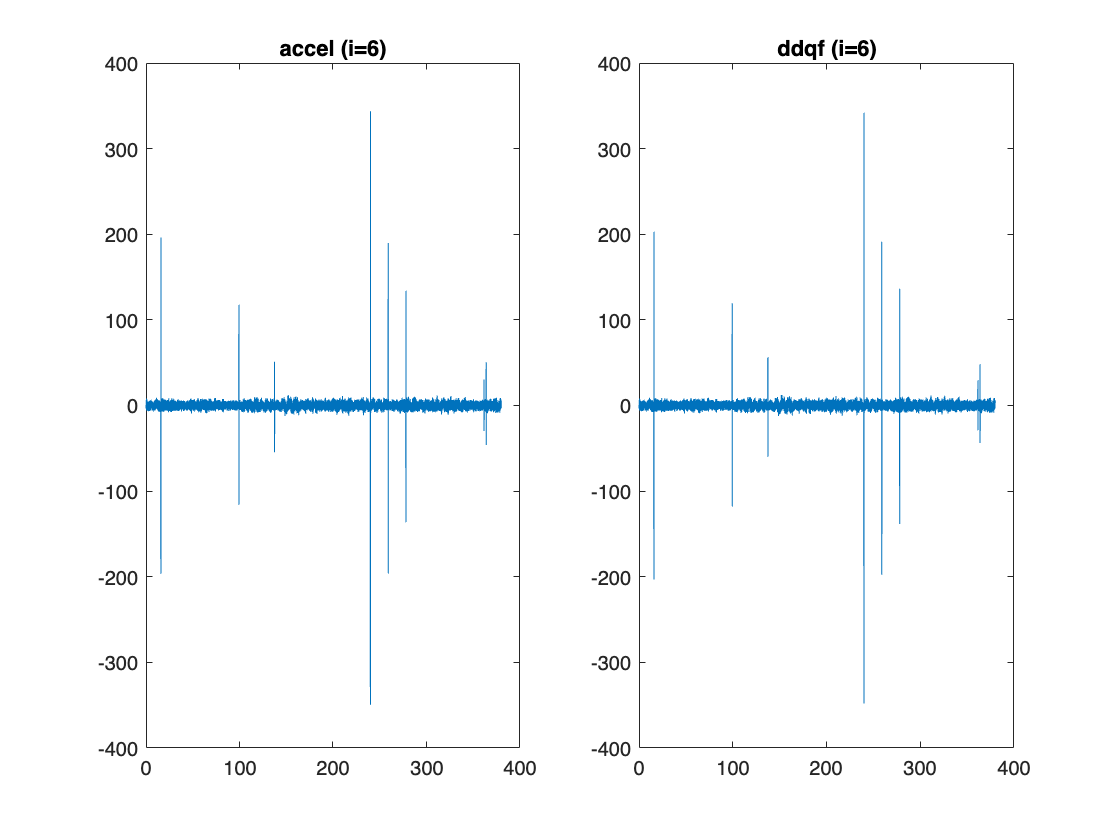

for i = 1:6
    f = figure('Name', sprintf('Joint Acceleration : q_%d', i)); 
    subplot(1,2,1); 
    plot(t, accel(i,:)); 
    title(sprintf('accel (i=%d)', i));
    subplot(1,2,2); 
    plot(t, ddqf(i,:));    
    title(sprintf('ddqf (i=%d)', i));
end

**Joint Torque**

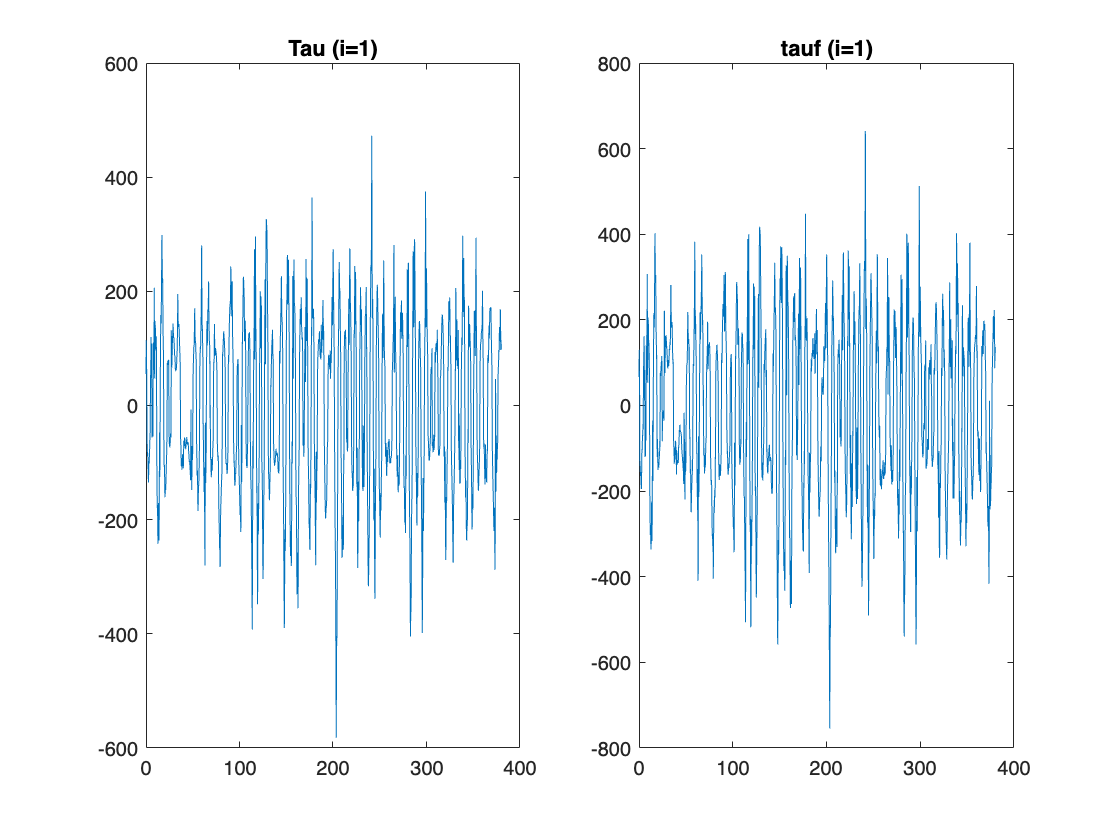

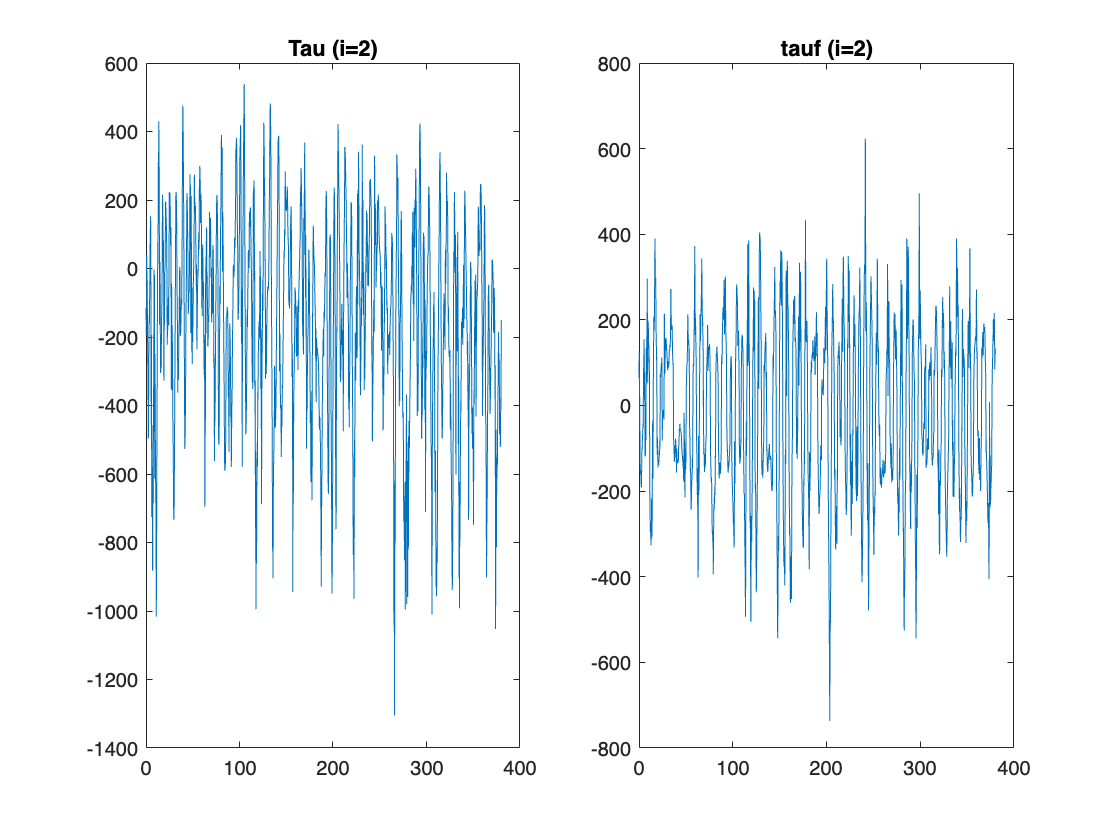

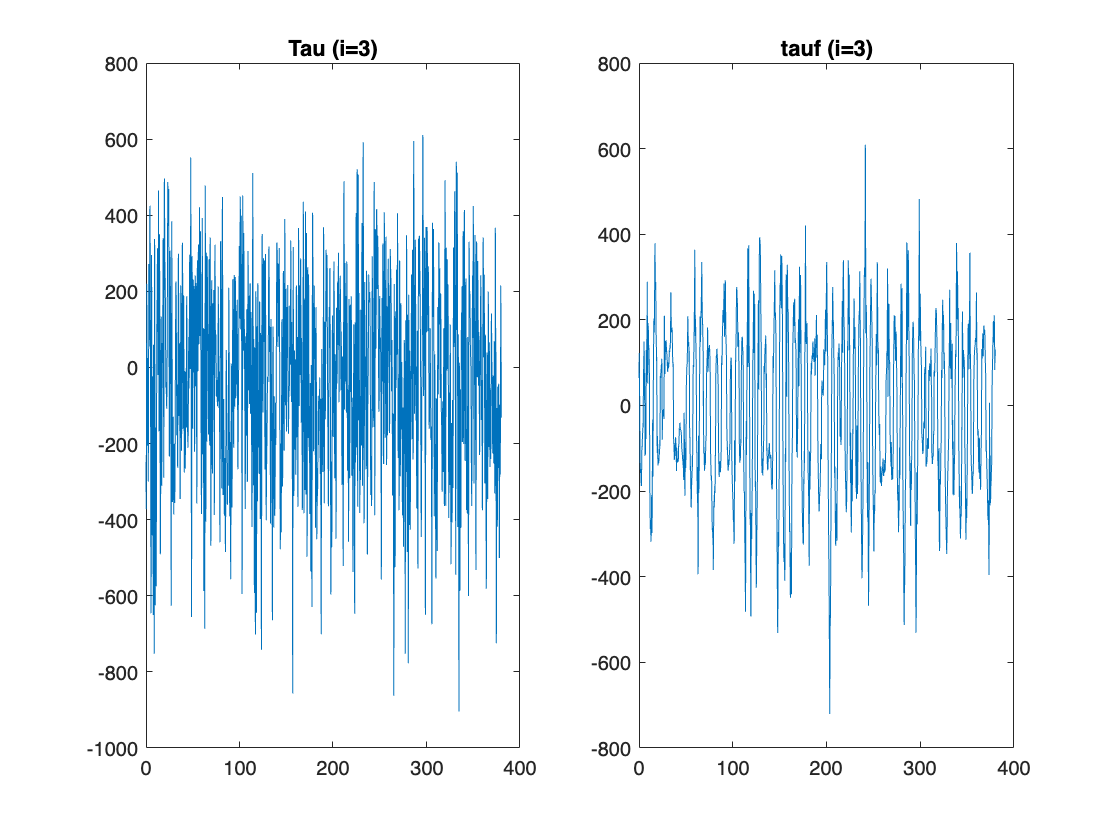

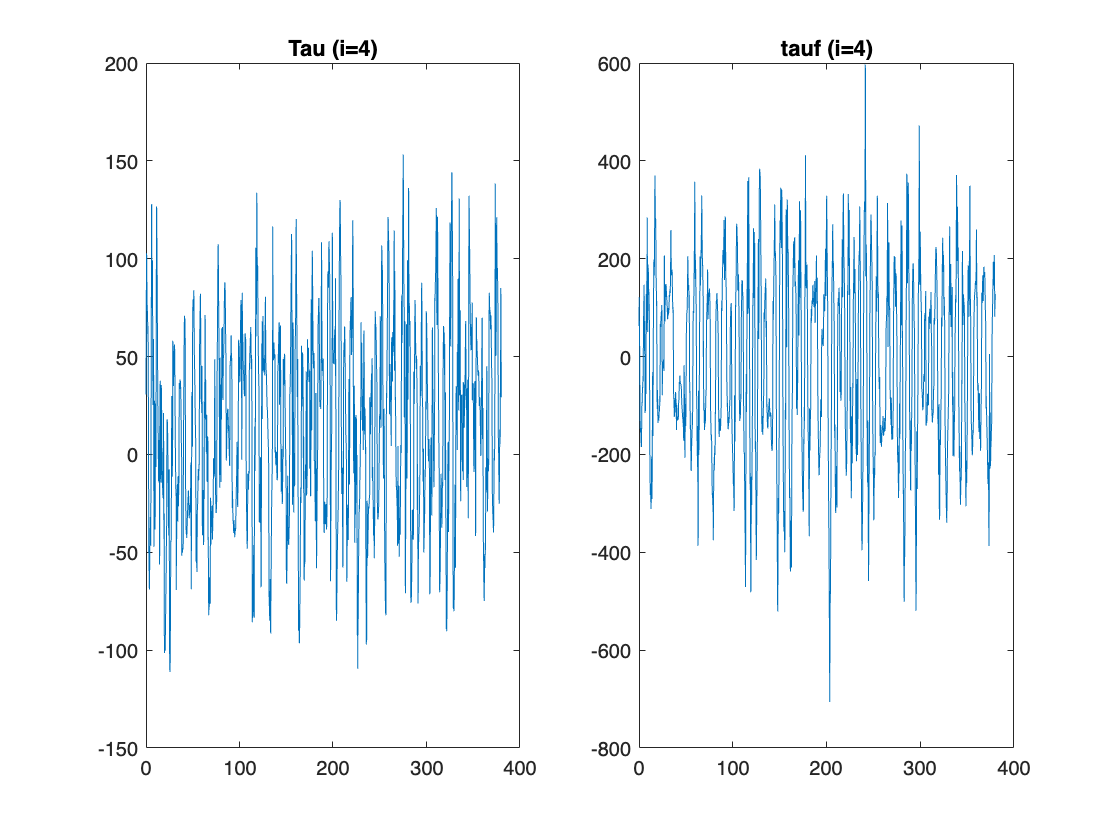

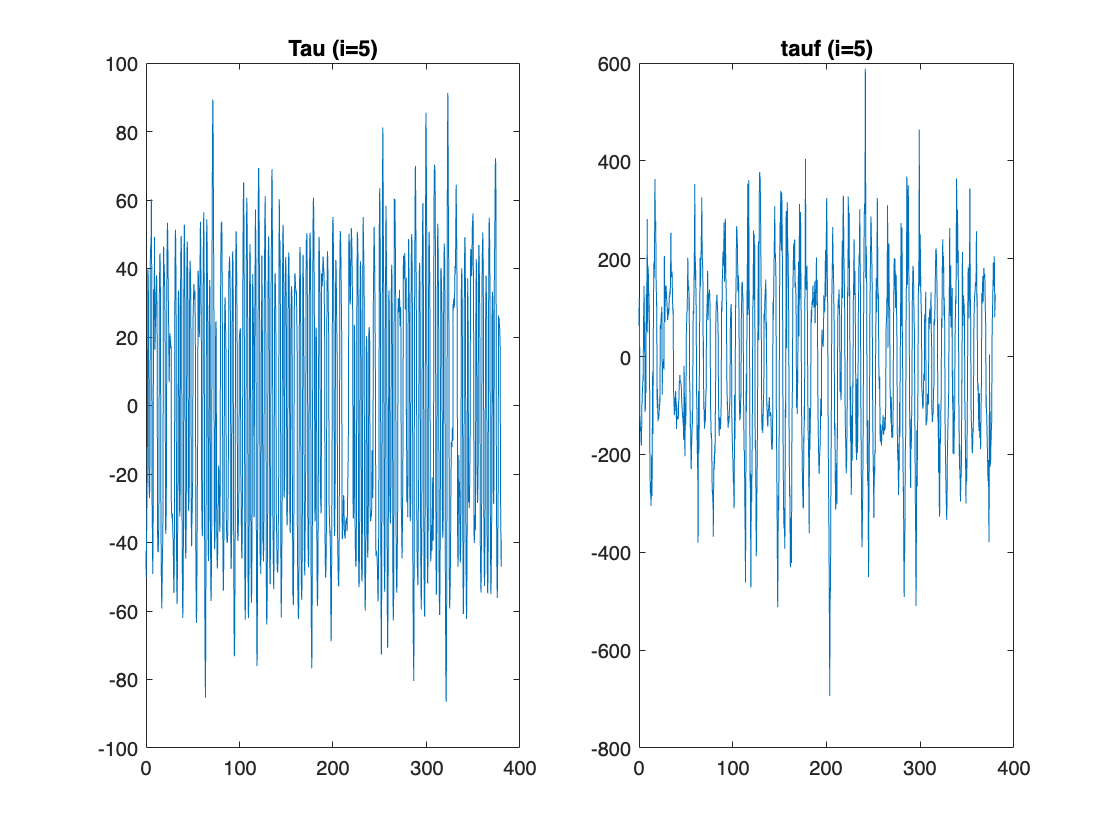

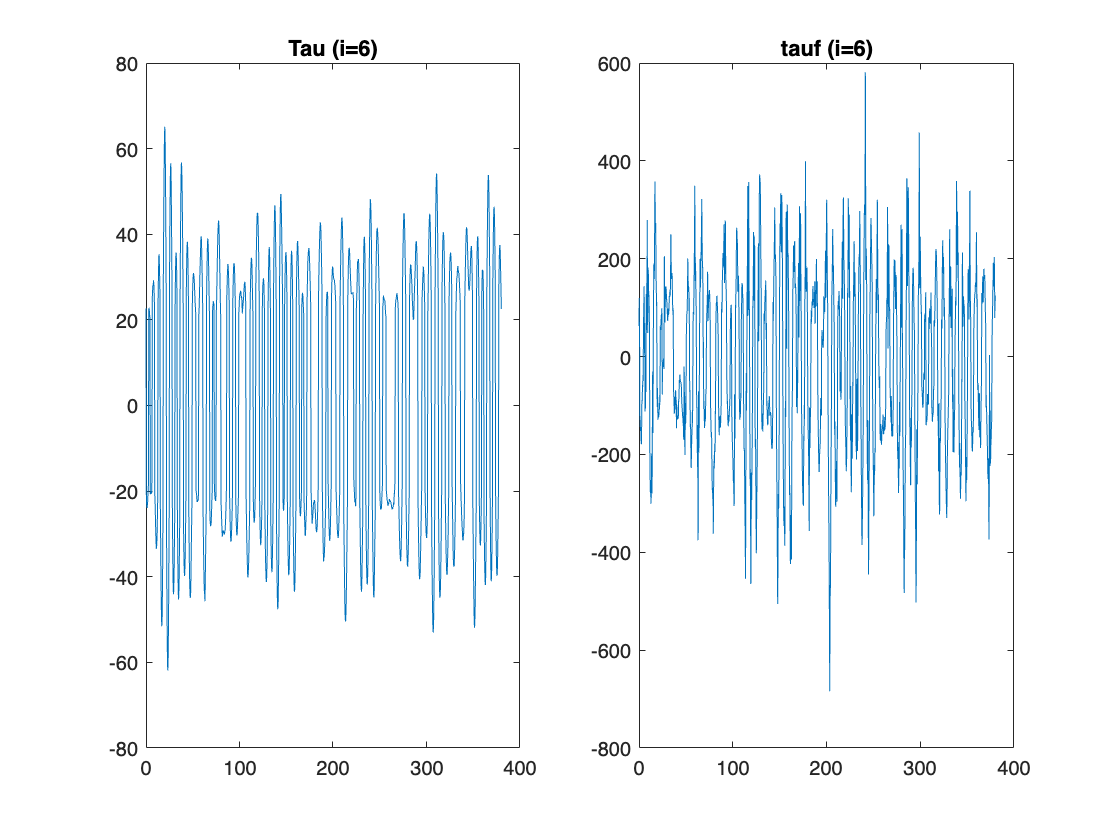

for i = 1:6
    f = figure('Name', sprintf('Joint Torque : q_%d', i)); 
    subplot(1,2,1); 
    plot(t, Tau(i,:)); 
    title(sprintf('Tau (i=%d)', i));
    subplot(1,2,2); 
    plot(t, tauf(i,:));    
    title(sprintf('tauf (i=%d)', i));
end

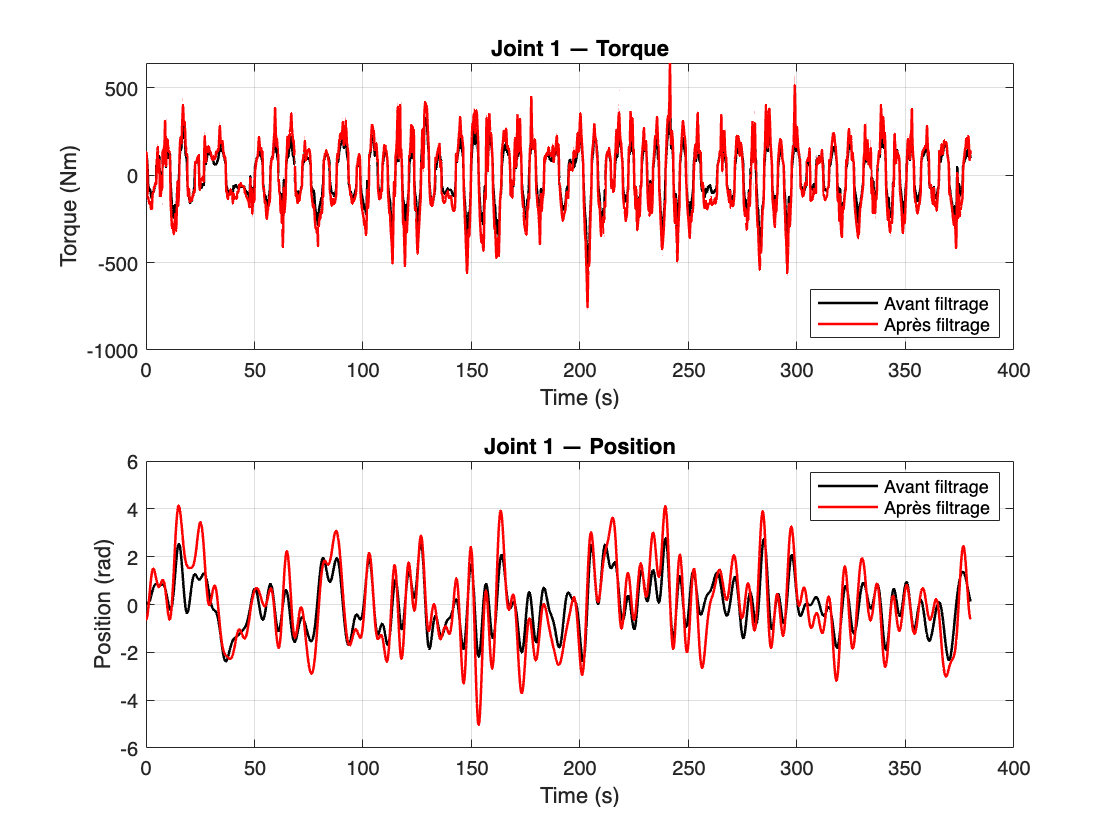

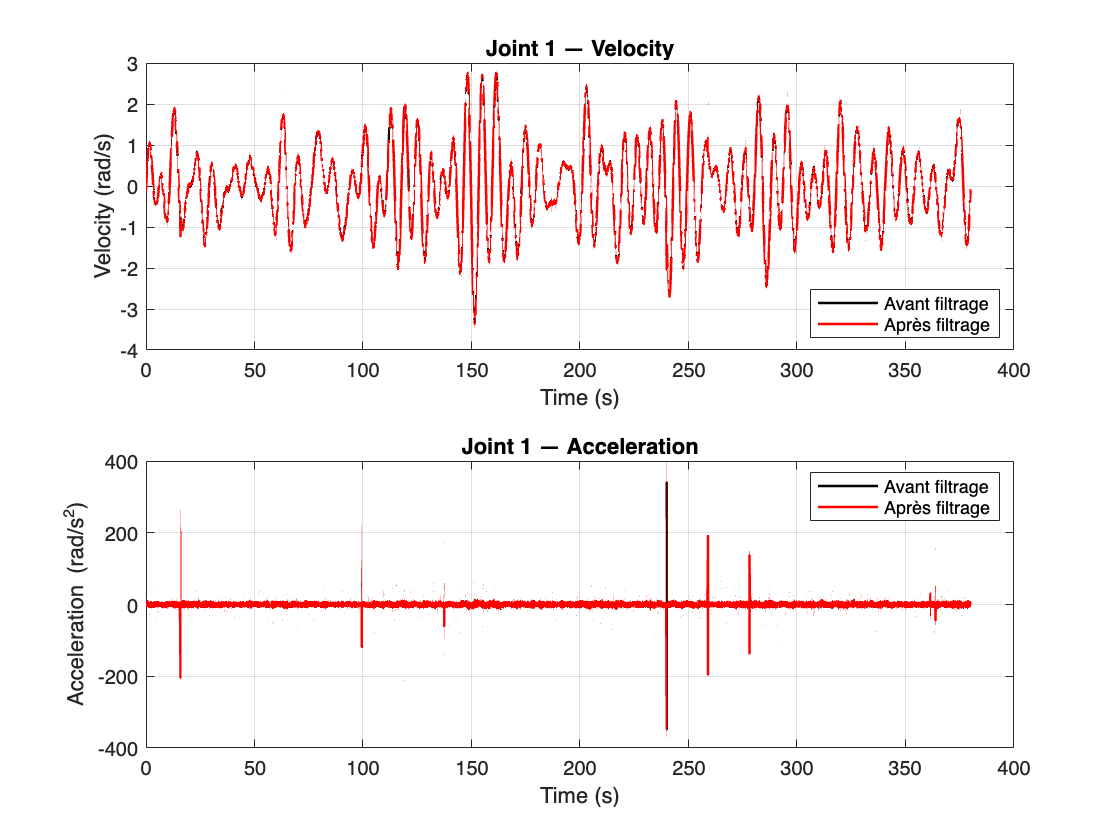

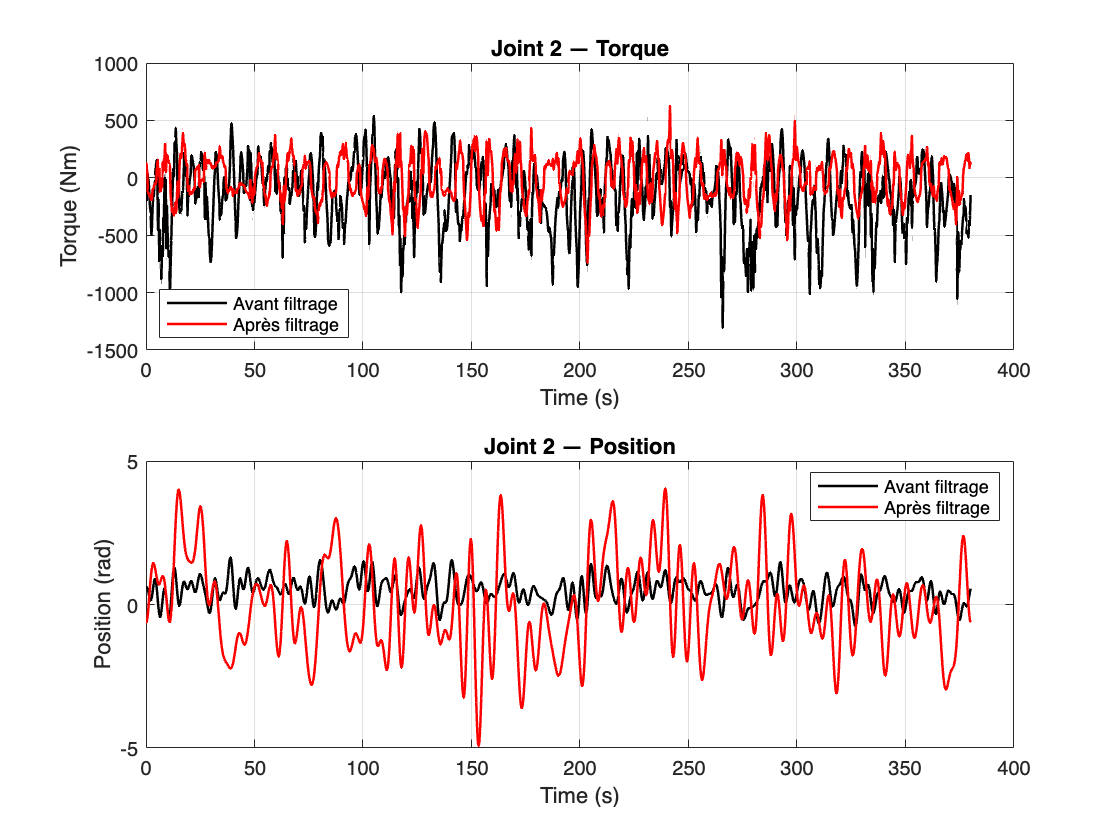

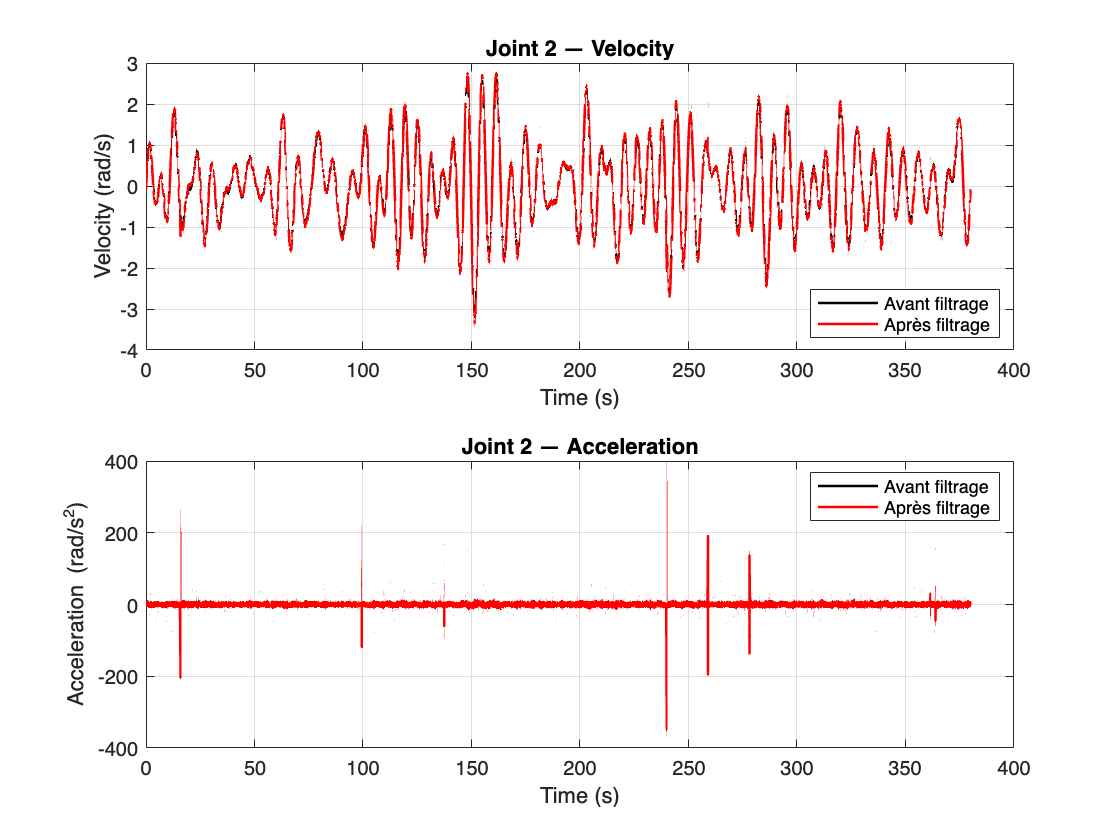

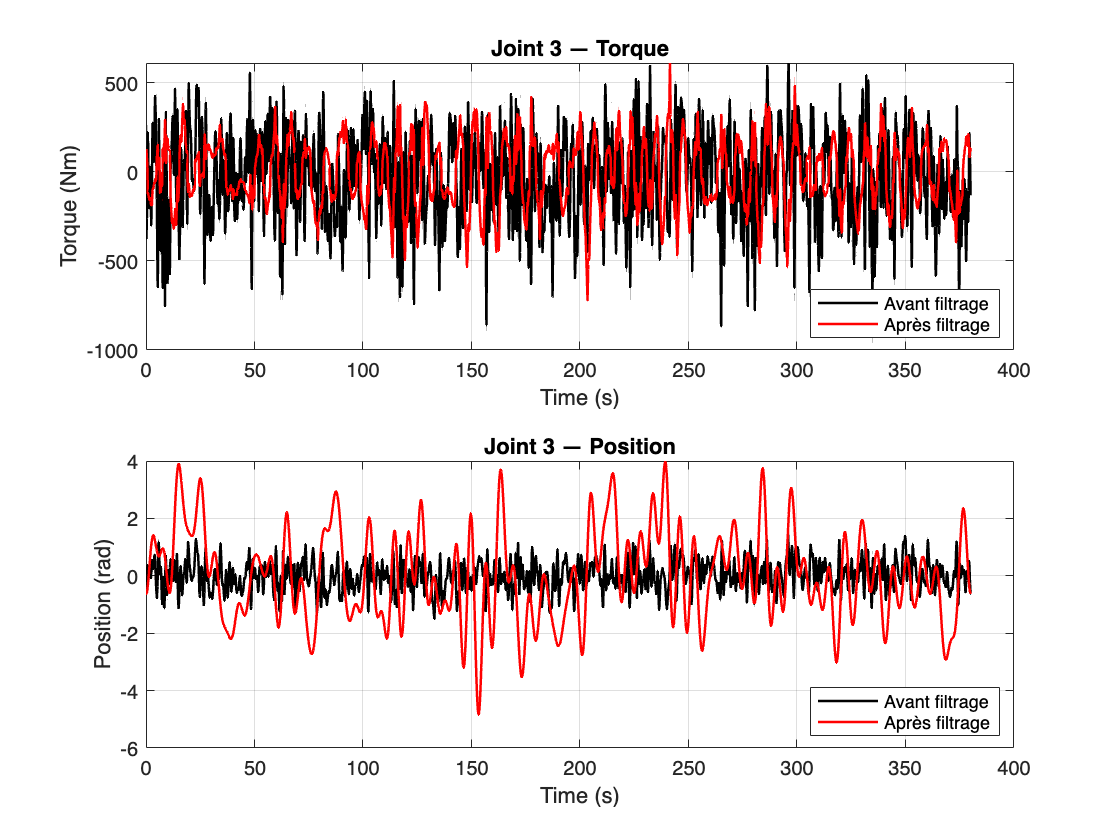

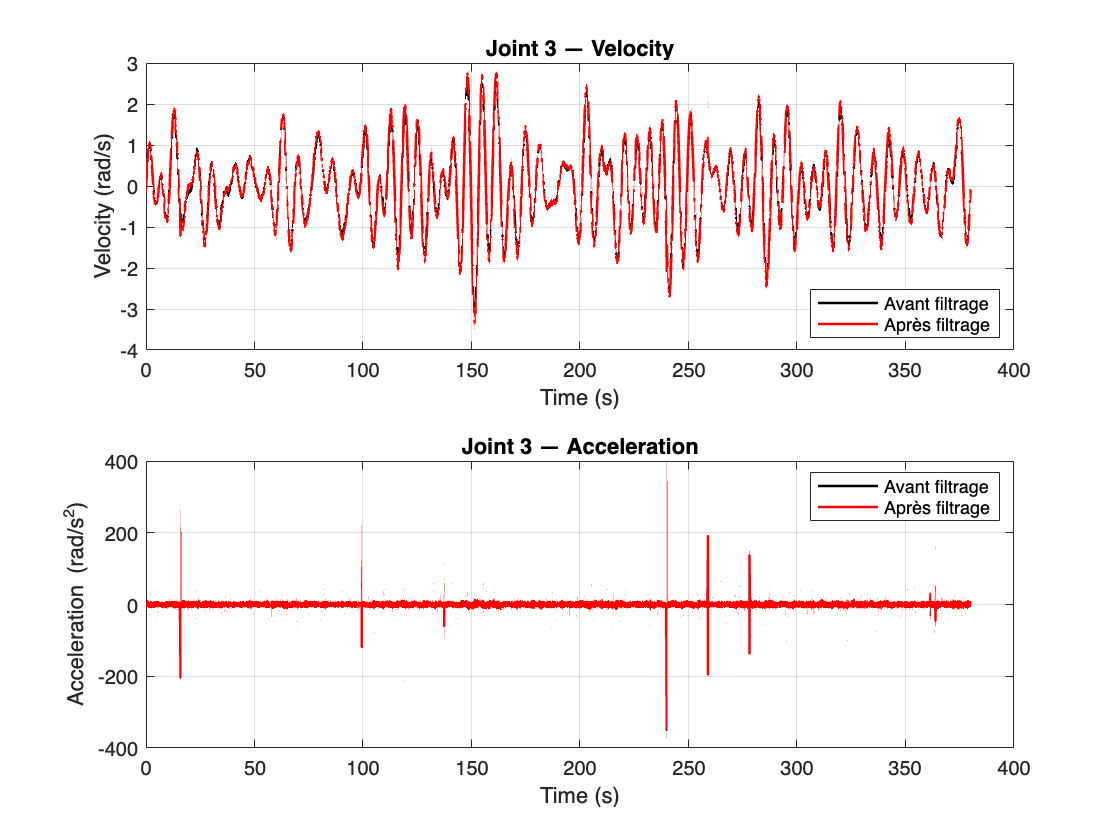

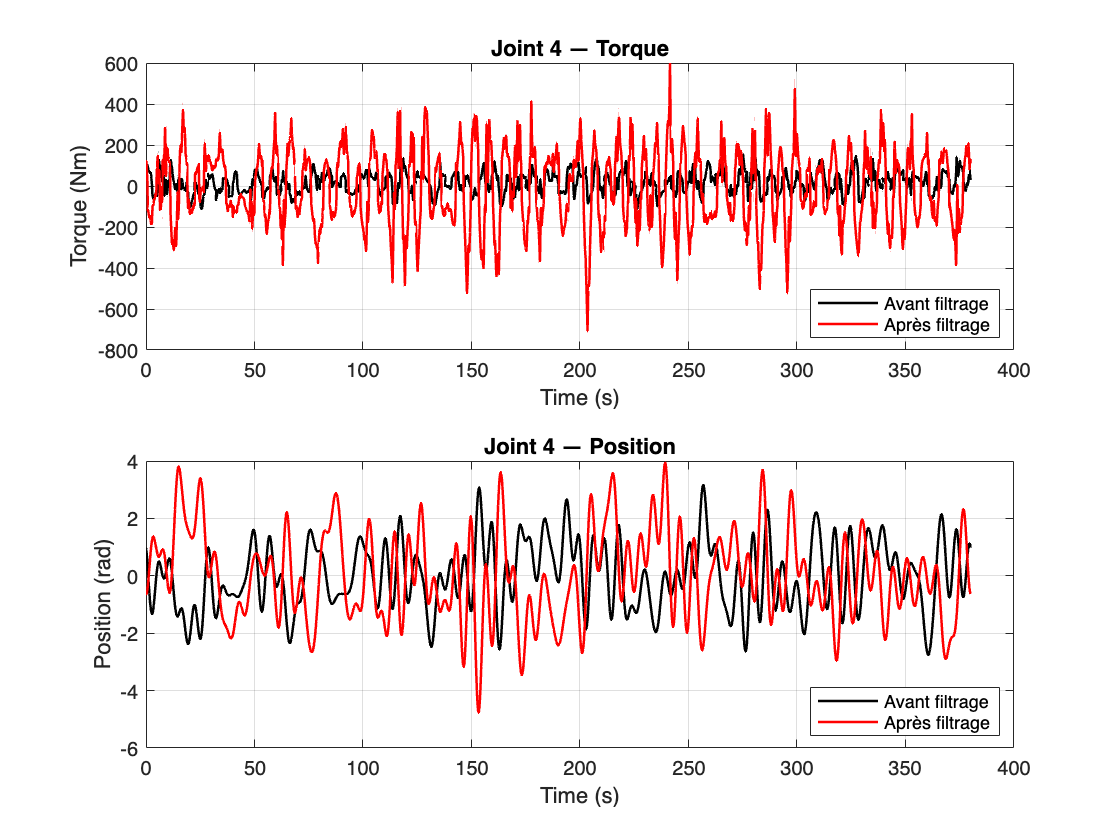

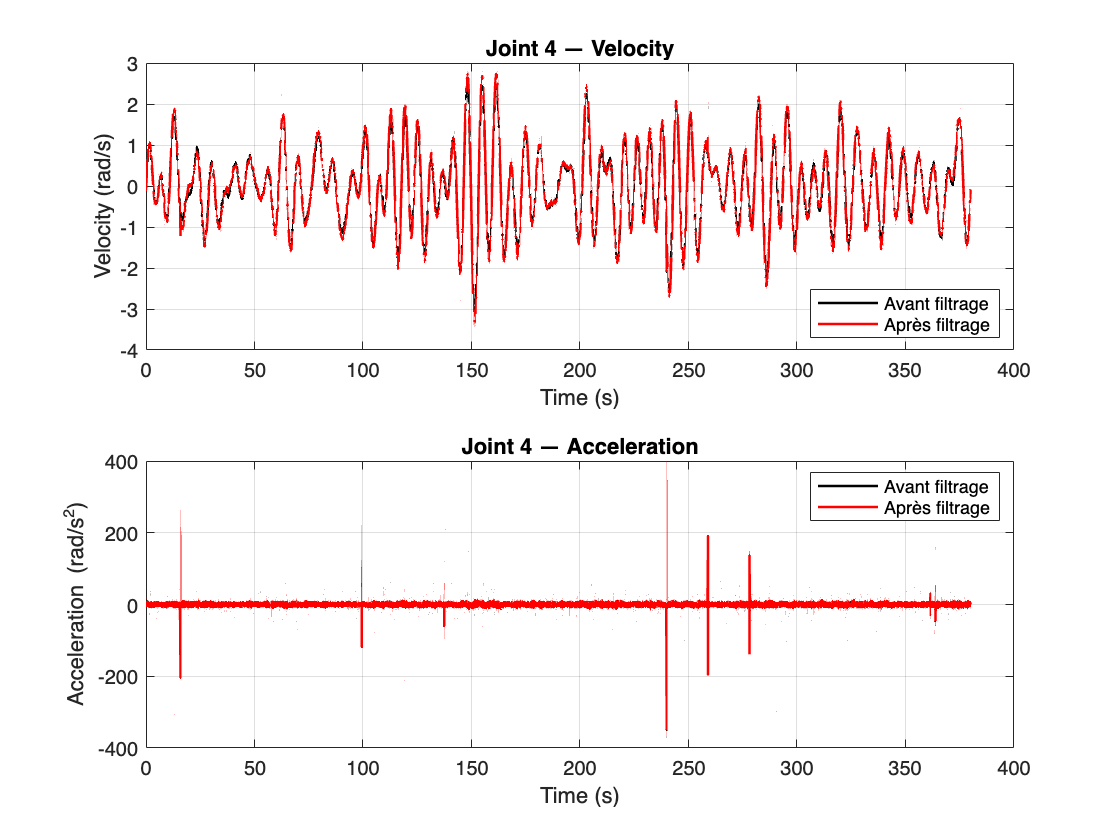

t = t(:);

for i = 1:6
    % Fig 1 : Torque (haut) et position (bas)
    f1 = figure('Name', sprintf('Joint %d — Torque & Position', i), 'NumberTitle','off');
    
    % Torque
    subplot(2,1,1);
    plot(t, Tau(i,:).', 'k-', 'LineWidth', 1.25, 'DisplayName', 'Avant filtrage'); hold on;
    plot(t, tauf(i,:).', 'r-', 'LineWidth', 1.25, 'DisplayName', 'Après filtrage'); 
    grid on; xlabel('Time (s)'); ylabel('Torque (Nm)');
    title(sprintf('Joint %d — Torque', i));
    legend('show', 'Location', 'best'); hold off;

    % Position
    subplot(2,1,2);
    plot(t, q_rad(i,:).', 'k-', 'LineWidth', 1.25, 'DisplayName', 'Avant filtrage'); hold on;
    plot(t, qf(i,:).',     'r-', 'LineWidth', 1.25, 'DisplayName', 'Après filtrage'); 
    grid on; xlabel('Time (s)'); ylabel('Position (rad)');
    title(sprintf('Joint %d — Position', i));
    legend('show', 'Location', 'best'); hold off;
    ax1 = findall(f1, 'Type', 'axes'); linkaxes(ax1, 'x');

    % Fig 2 : Velocity (haut)  et acceleration (bas)
    f2 = figure('Name', sprintf('Joint %d — Velocity & Acceleration', i), 'NumberTitle','off');

    % Velocity
    subplot(2,1,1);
    plot(t, velo(i,:).', 'k-', 'LineWidth', 1.25, 'DisplayName', 'Avant filtrage'); hold on;
    plot(t, dqf(i,:).',   'r-', 'LineWidth', 1.25, 'DisplayName', 'Après filtrage'); 
    grid on; xlabel('Time (s)'); ylabel('Velocity (rad/s)');
    title(sprintf('Joint %d — Velocity', i));
    legend('show', 'Location', 'best'); hold off;

    % Acceleration
    subplot(2,1,2);
    plot(t, accel(i,:).', 'k-', 'LineWidth', 1.25, 'DisplayName', 'Avant filtrage'); hold on;
    plot(t, ddqf(i,:).',  'r-', 'LineWidth', 1.25, 'DisplayName', 'Après filtrage'); 
    grid on; xlabel('Time (s)'); ylabel('Acceleration (rad/s^2)');
    title(sprintf('Joint %d — Acceleration', i));
    legend('show', 'Location', 'best'); hold off;
    ax2 = findall(f2, 'Type', 'axes'); linkaxes(ax2, 'x');
end